# NB-IoT SDR Receiver Filter Design

## 1) Block Diagram

        The transmission and receiving Radio frequency (RF) is chosen to be equal to 1.95 GHz so that it can be send through LTE Band 1 Uplink which ranges from 1.92 GHz and 1.98 GHz. The IF frequency is chosen to be 800 KHz which the filter is designed upon.

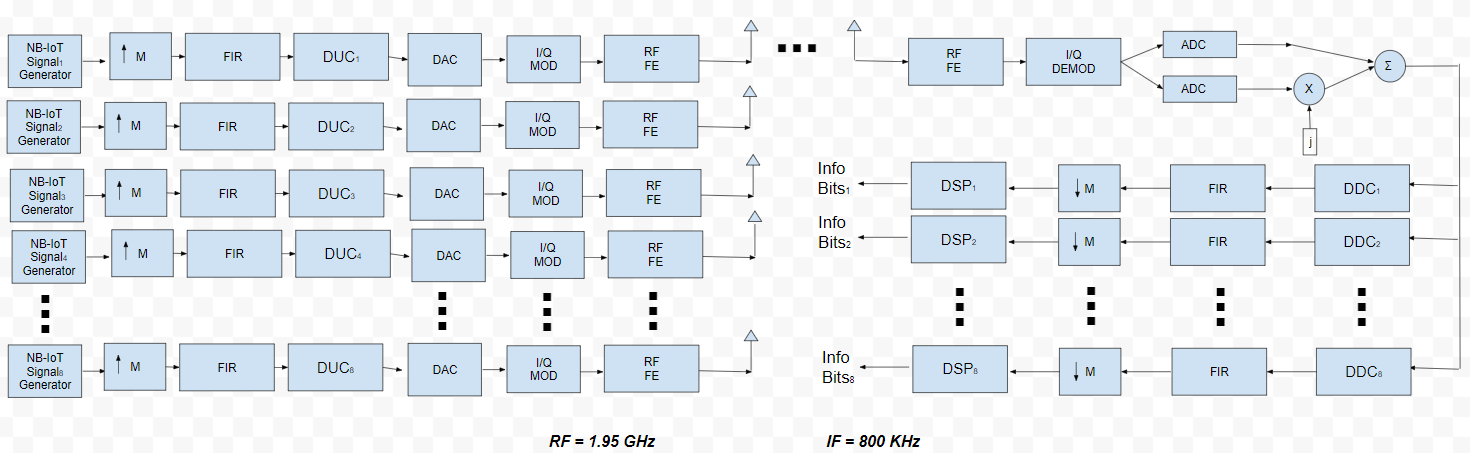

## 2) Filter Design Process

### **    Problem Statement :**

        In the process of designing an efficient IoT system, competent filter design is an essential step that ensures smooth interaction between devices that make up the network. Looking at the IoT spec we see that we will be transmitting eight Frequency-Division Multiplexed signals that each occupy 180KHz with a separation of 20KHz between each frequency band. With this in mind, and the importance of accurate signal transmission in such applications as IoT, we can see that we will need a filter with a slim transition region, strong stopband attenuation, and minimal passband ripples and passband attenuation. These constraints are inversely proportional with another constraint in our design process; the filter order, which we aim to minimize so that the filtering process is not computationally complex, thus risking our filter to be costly and slow when implemented as hardware. Therefore, our aim is to find the most reasonable compromise that can ensure efficient, and accurate signal transmission.

### **    Design Constraints:**

#### **         Passband and Stopband attenuation:**

                Seeing as each signal’s frequency span ends at 90KHz, and the end of the separation band is at 110KHz, The Passband attenuation will have to not exceed 3dB (0 to 90 KHz), and the stopband attenuation will have to be at 20dB or more (110 KHz or more) to ensure no interference between two subsequent bands occurs. 

#### **        Transition Region:**

            As is specified in the format 1 transmission spec, the spacing between the center frequencies of each two subsequent uplink signals is 200 KHz. With this in mind, and the fact that each signal takes up 180KHz, we are left with the constraint of the transition region being no wider than 25KHz, having attenuation of at least 15 dB at the 20KHz mark of the transition region. This is essential to avoid interference and distortion of transmission data.

#### **         Filter Order:**

            Even though a higher-order filter resembles an ideal filter more closely than a lower order filter, higher filter orders correspond to more multiplications and therefore pose a computational load that will hinder the performance of the entire system. Consequently, we need to minimize the filter order to a point where the other constraints are not violated to ensure the efficacy of our solution.

### **Filter Prototypes and Design Iterations:**

### **Filter 1:**

Filter design method:** Least squares **

#### Specs:

- Order = 256

- Δp = 0.0335, passband ripples= 0.3 dB

- Δs = 0.0865, stopband attenuation= - 29.5 dB

- Transition band = 0.0216 MHz

- Fpass=90

- Fstop=100

- Wpass=10 

- Wstop=1

This filter is a competent contender due to its low passband ripples, high stopband attenuation, low passband attenuation and small transition band that are all within the specified constraints. The order is somewhat high, nonetheless.

 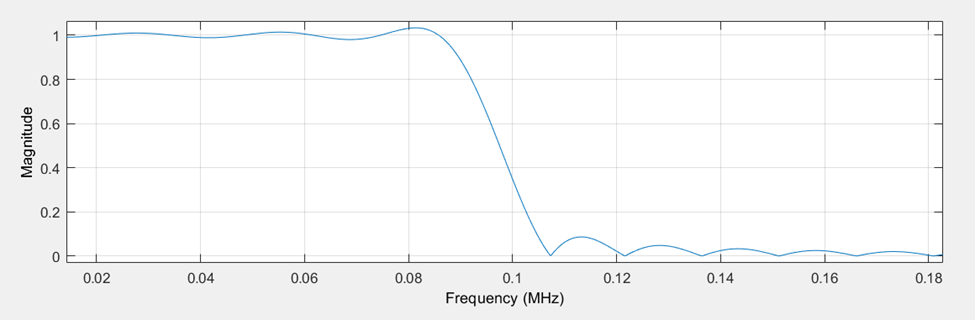

### **Filter 2:**

Filter design method:** Least squares**

#### Specs:

- Order=132

- Δp = 0.0433, passband ripples= 0.38 dB

- Δs = 0.1355, stopband attenuation= - 17.36 dB

- Transition band = 0.0354 MHz

- Fpass=90

- Fstop=95

- Wpass = 10 

- Wstop =1

This filter will not fit our use case due to its large transition band. The  stopband attenuation and passband ripples are within our specified constraints, and the order of the filter is the previous filter.

 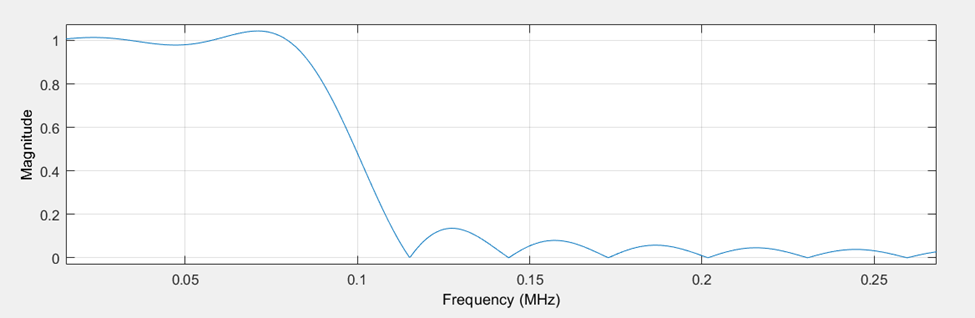

### **Filter 3:**

Filter design method: **Equiripple**

#### Specs:

- Order=196

- Δp = 0.0254, passband ripples= 0.22 dB

- Δs = 0.254, stopband attenuation= - 11.9 dB

- Transition band = 0.0209 MHz

- Fpass=90

- Fstop=105

- Wpass=10

- Wpass=1

This filter has a small transition region, respectable passband attenuation and minimal passband ripples. However, stopband attenuation is subpar, and the order is not as good as other contenders.

 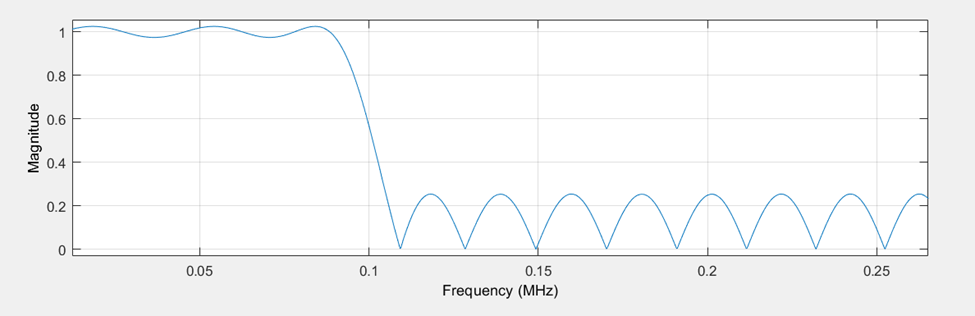

### **Filter 4:**

Filter design method: **Kaiser**

#### Specs:

- Order = 226

- Δp = 0.0853, passband ripples= 0.77 dB

- Δs = 0.0537, stopband attenuation= - 25.4 dB

- Transition band = 0.0234 MHz

- Fpass=90

- Fstop=110

- Apass=1

- Astop=20

This filter has a small transition region, high stopband attenuation, and minimal passband ripples. The order is somewhat high and passband attenuation is high, nonetheless.

 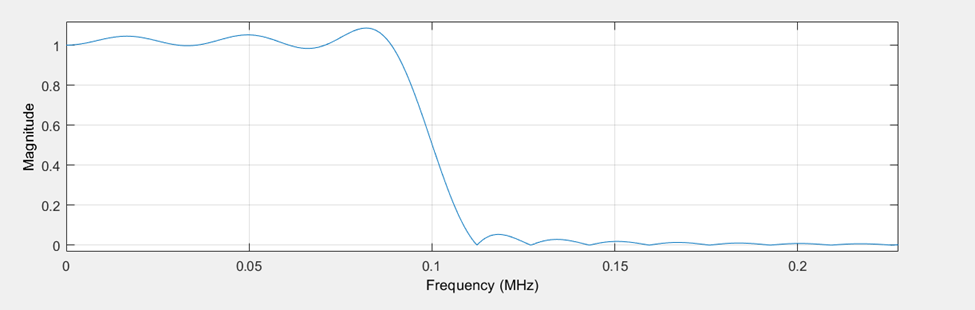

### **Filter 5:**

Filter design method: **Kaiser**

#### Specs:

- Order = 181

- Δp = 0.0422, passband ripples= 0.3745 dB

- Δs = 0.061, stopband attenuation= - 24.3 dB

- Transition band = 0.0305 MHz

- Fpass=85

- Fstop=110

- Apass=1

- Astop=20

This filter has low passband attenuation, minimal passband ripples, high stopband attenuation and a reasonable filter order. The transition band violates the constraints we set, however.

 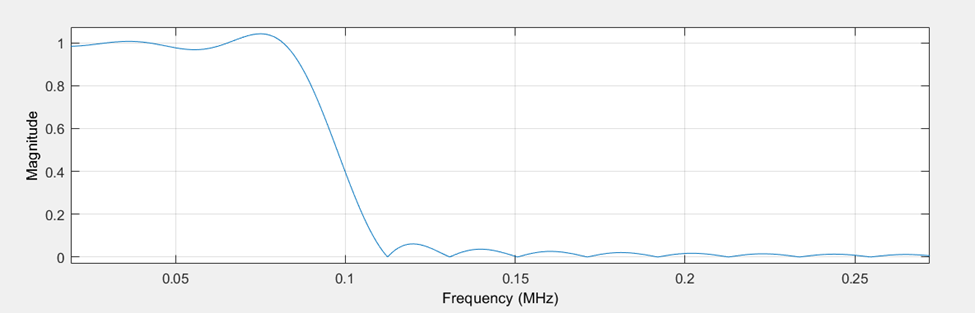

The 226 Kaiser filter is the closest to being our desired optimal filter bounded by the constraints we set, followed by the 256 Least squares filter, which was only disqualified due to its higher complexity that was accompanied by diminishing returns when it came to improvements over the 226 Kaiser. 

## 3) Simulation

##  NB-IoT Signals Transmission    

###     Generation of 8 NB-IoT Waveforms

        The waveforms are assumed to be generated from 8 different NB-IoT devices transmitting their up-link signals to a base station according to LTE-Advanced Pro Release 13. We used MATLAB LTE toolbox to generate the standard compliant NB-IoT uplink complex baseband waveforms representing the 180 kHz narrowband carrier.

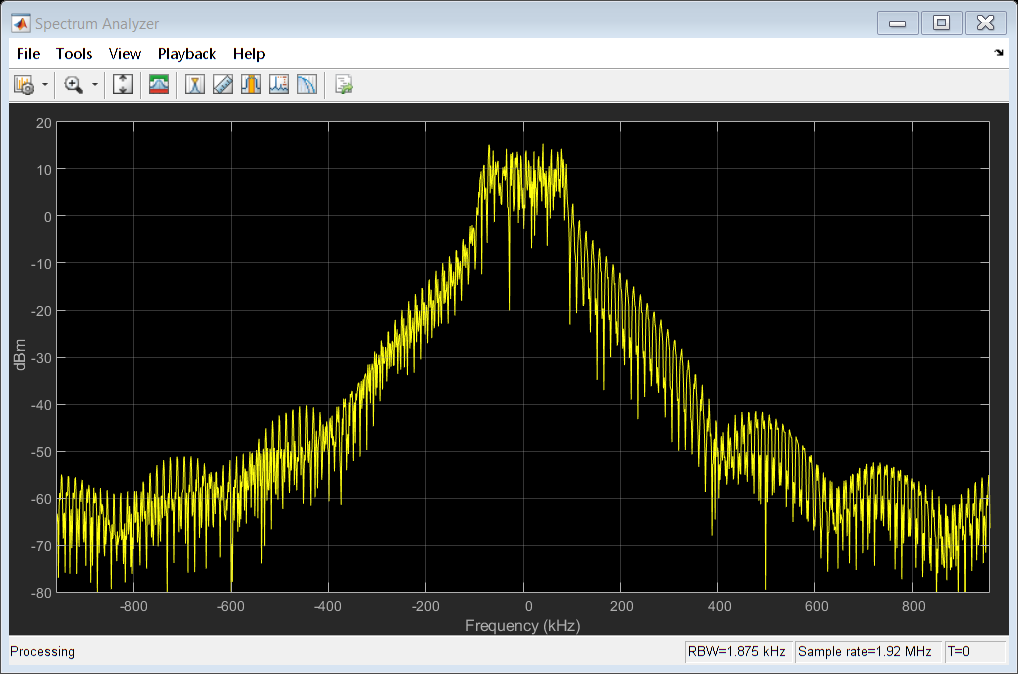

clear; clc; close all;
transmittedSignals = [];
N = 8;
for i = 1:N
    [signal, fs] = GenerateUpLinkWaveForm(i);
    if i==1
    figure;
    spec1 = dsp.SpectrumAnalyzer('SampleRate',fs);
    spec1(signal);
    end
    transmittedSignals(i,:) = signal;
end

ts = 1/fs;
n = 0 : length(transmittedSignals(1))-1;
frequencySpan = 180e3;
frequencySpacing = 200e3;
IF1 = 1e5;
IF = IF1:frequencySpacing:IF1+N*frequencySpacing;

###     Upsampling the Generated Signals

            The signals are upsampled to increase the sampling frequencies of the generated signals to be able to be represented in the IF signal that consists of the 8 NB-IoT signals. Having the IF at 800 KHz leads to having a sampling frequency of 3.84 MHz.

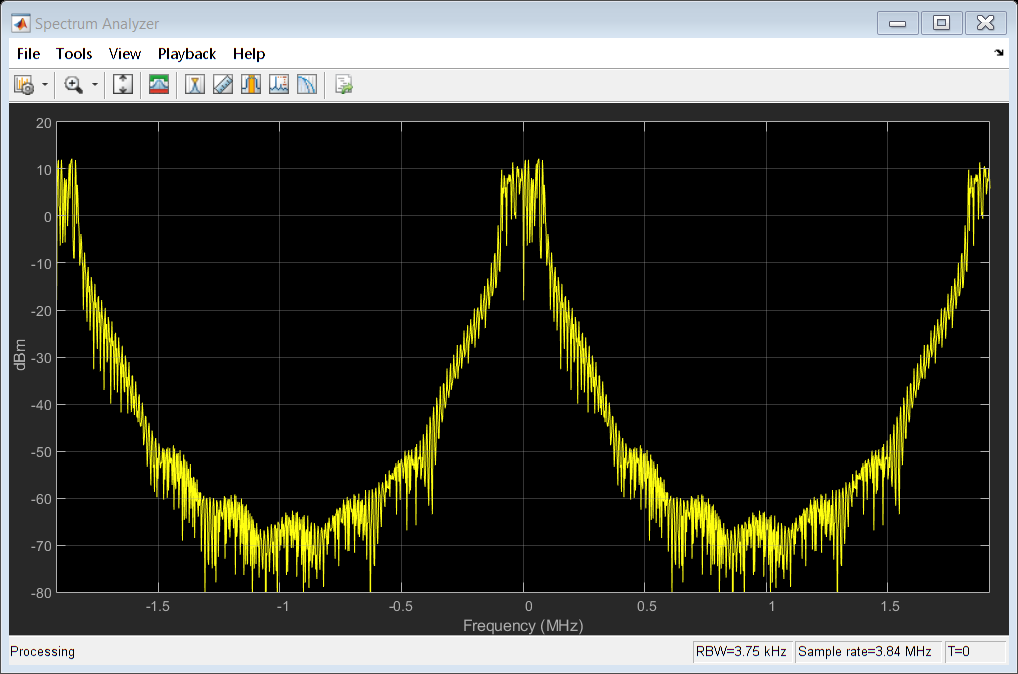

M = 2;
upSampledfs = M*fs; 
while (upSampledfs/2 < IF(end))
    M = M + 1;
    upSampledfs = M*fs;
end
upsampledTransmittedSignals = upsample(transmittedSignals',M)';
figure
spec2 = dsp.SpectrumAnalyzer('SampleRate',upSampledfs);
spec2(upsampledTransmittedSignals(1,:)')

###   Applying the Transmitter FIR Designed Filter

        The designed filter is applied to the upsampled signal after the design process mentioned in Section 2 to get the 180 KHz span of the signal only according to the standard.

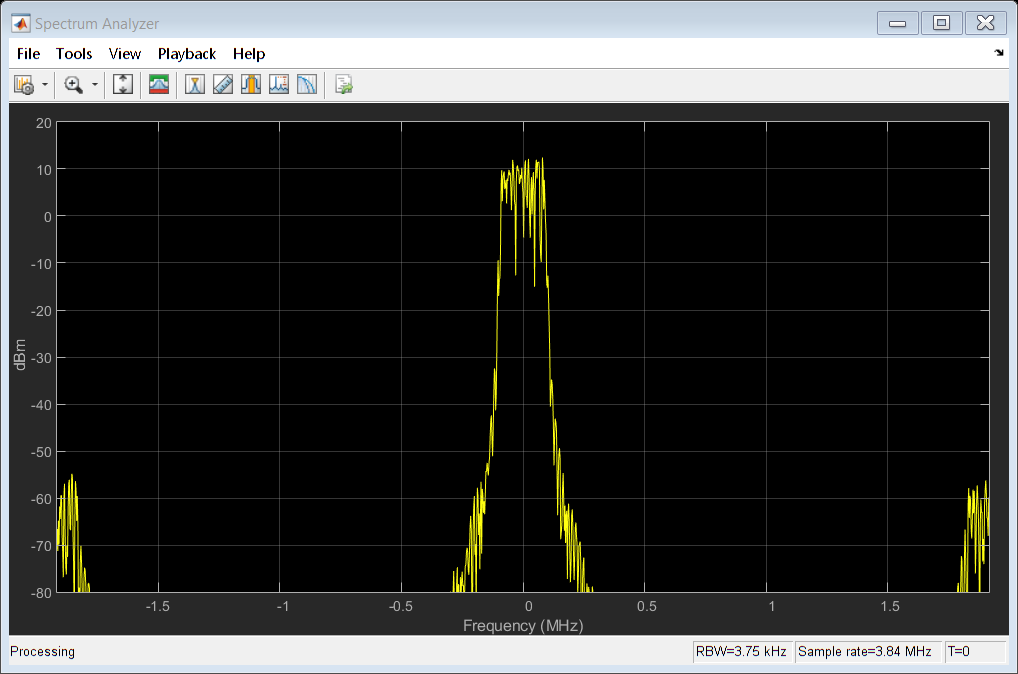

load('filtercoef.mat')
filteredSignals=[];
for i = 1:N
filteredSignals(i,:)=filter(filtercoef,1,upsampledTransmittedSignals(i,:));
end
figure;
spec3 = dsp.SpectrumAnalyzer('SampleRate',upSampledfs);
spec3(filteredSignals(1,:)')

###     Applying the Digital Up Converter

        The filtered signals are passed by a Digital Up Converter (DUC) so that each signal will be shifted to its IF frequency starting from IF1 = 100 KHz till IF8 = 1.5 MHz.

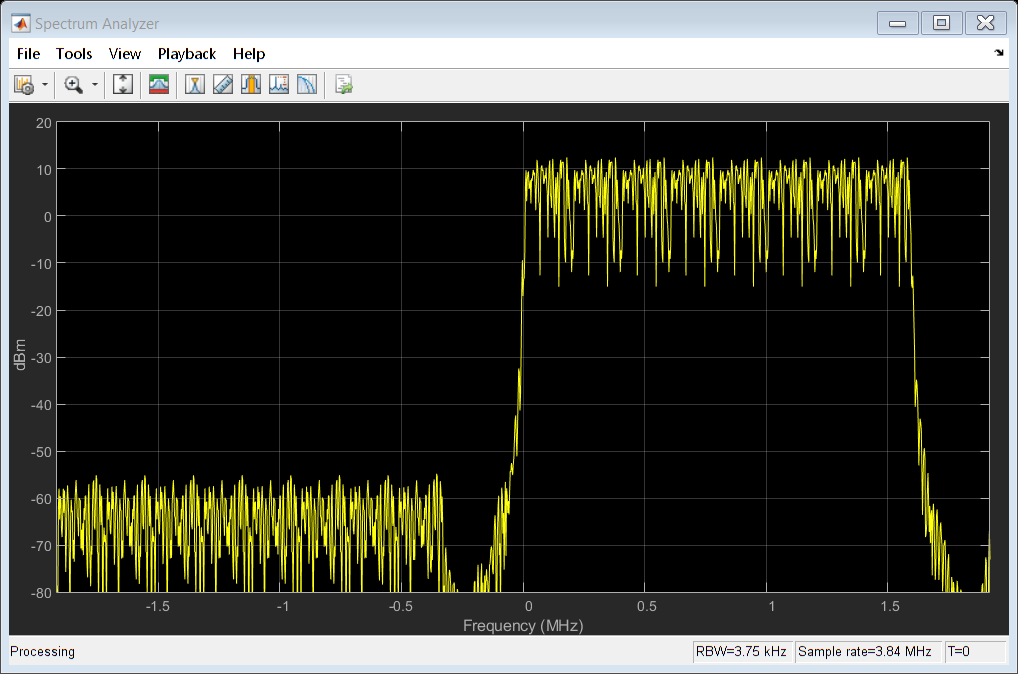

upSampledts = 1/upSampledfs;
upSampledn = 0 : length(upsampledTransmittedSignals(1,:))-1;
DUCSignal = zeros(1,length(upsampledTransmittedSignals(1,:)));
DUCSignals = [];
for i = 1:N
    DUCSignal = DUCSignal + filteredSignals(i,:) .* exp(-1i * 2 * pi() * IF(i) * upSampledn * upSampledts);
end
figure;
spec4 = dsp.SpectrumAnalyzer('SampleRate',upSampledfs);
spec4(DUCSignal')

## Base Station Receiver

###     Applying the Digital Down Converter

            The Digital Down Converter is applied to the received IF signal so that each NB-IoT signal's frequency response is centered at 0 Hz so that filter can easily filter it.

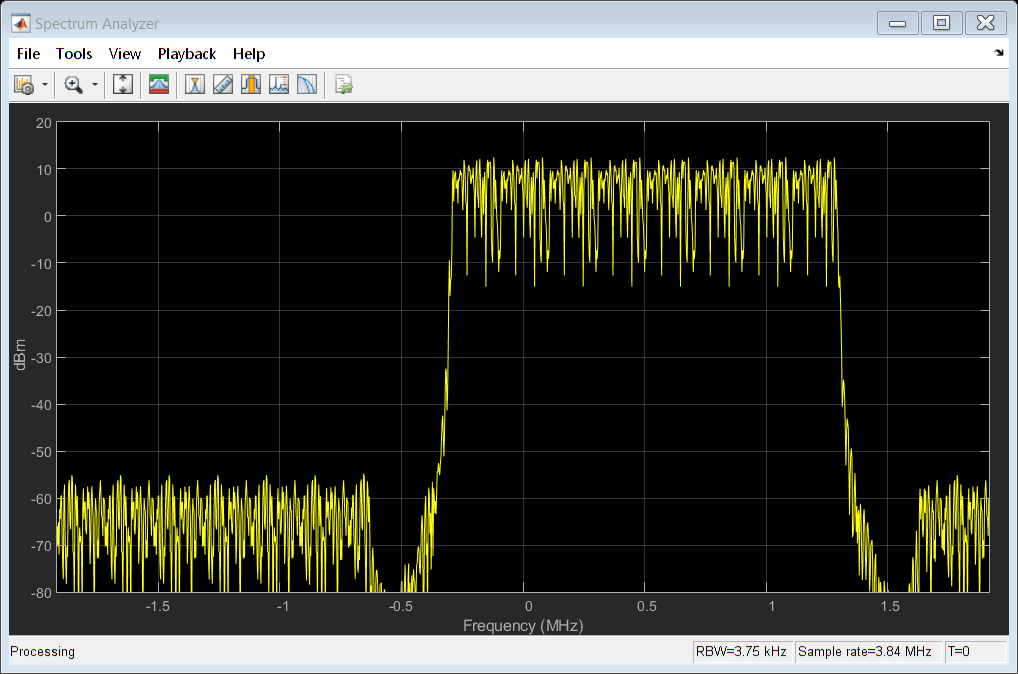

DDCSignals = [];
for i = 1:N
    DDCSignals(i,:) = DUCSignal .* exp(1i * 2 * pi() * IF(i) * upSampledn * upSampledts);
end
figure;
spec5=dsp.SpectrumAnalyzer('SampleRate',upSampledfs);
spec5(DDCSignals(1,:)');

###     Applying the FIR Designed Filter

            After the design process mentioned in Section 2, the designed filter is applied to the DDC signals to get each NB-IoT signal.

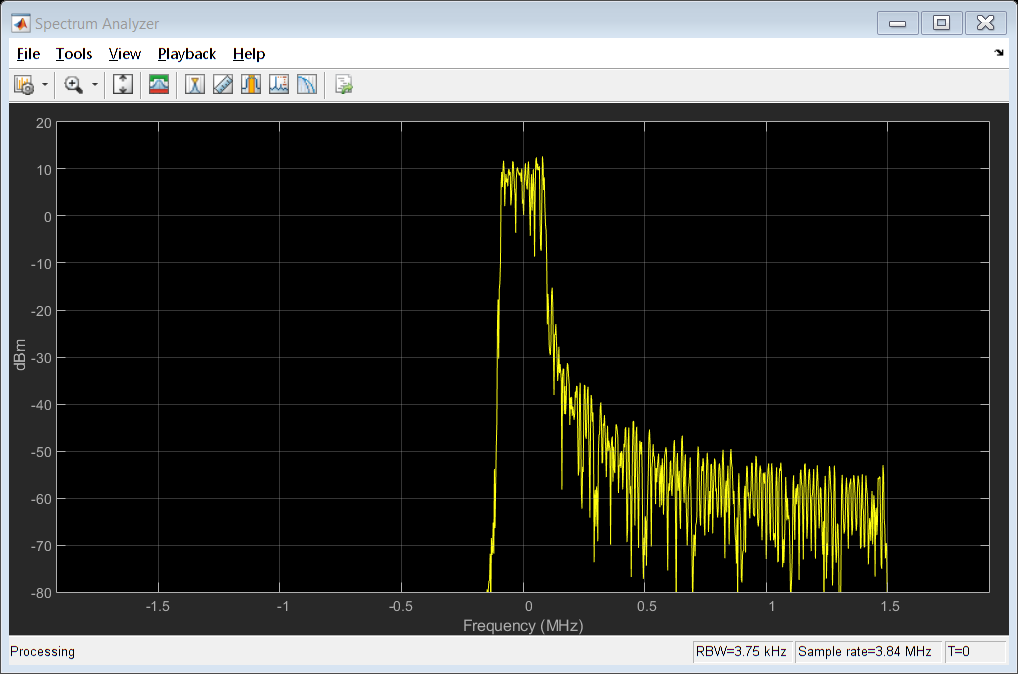

receivedFilterSignals = [];
for i = 1:N
    receivedFilterSignals(i,:) = filter(filtercoef,1,DDCSignals(i,:));
end
spec6=dsp.SpectrumAnalyzer('SampleRate',upSampledfs);
step(spec6,receivedFilterSignals(1,:)');

###     Downsampling the Received Signal 

            The downsampling is applied to retain the original sampling frequency of each of the eight NB-IoT received signals.

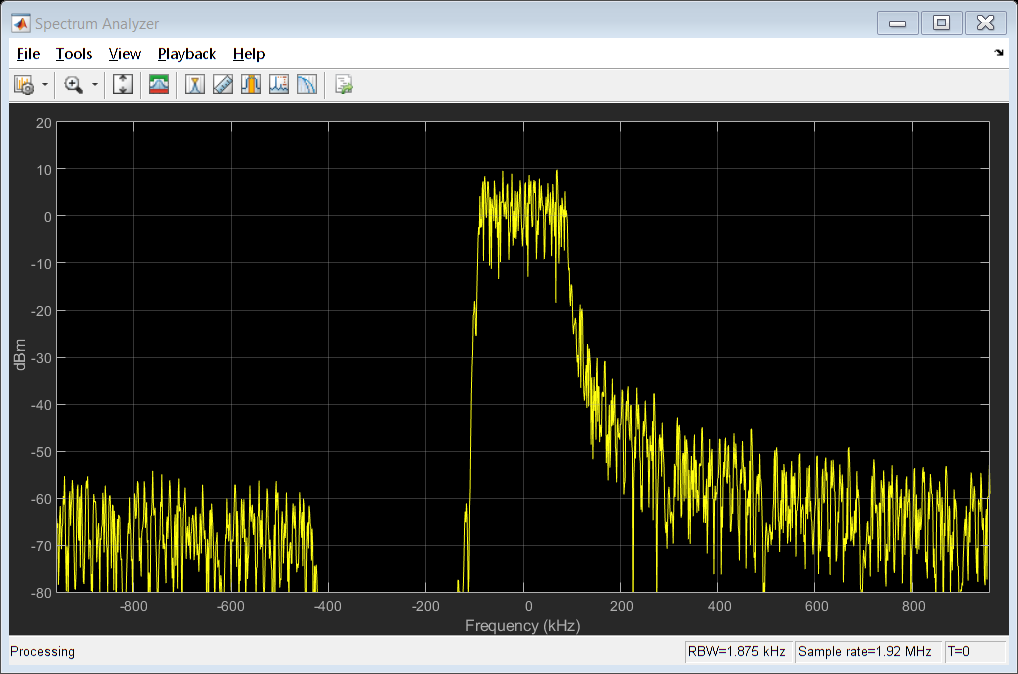

downsampledReceivedSignals = downsample(receivedFilterSignals',M)';
figure;
spec7=dsp.SpectrumAnalyzer('SampleRate',fs);
step(spec7,downsampledReceivedSignals(1,:)');

## 4) NB-IoT Applications Effect on Public Safety

    Internet of Things (IoT) is a system of interrelated, wireless, and connected digital devices that are mainly used to store, and send data over networks without requiring human interactions. The IoT offered various benefits when coming to streamlining and boosting health care delivery to proactively predict health problems and diagnose, monitor, and treat patients despite their given locations whether they were at the hospital or anywhere else. Due to the current COVID-19 pandemic, there has been an increased demand for applying IoT technology. However, obstacles hindering this technology from spreading fast are a great concern all over the globe. For instance, barriers to market adoption from health care professionals and patients alike, confidence and acceptability, privacy and security, interoperability, standardization and remuneration, data storage, and control and ownership are the challenges slowing down this technology to grow and flourish.

## 5) Reference

- *LTE frequency bands explained: Kajeet Iot Solutions*. Kajeet, Inc. (n.d.). Retrieved January 9, 2022, from https://www.kajeet.net/resource/lte-frequency-bands-explained/ 

- Kelly, J. T., Campbell, K. L., Gong, E., & Scuffham, P. (2020). The internet of things: Impact and implications for Health Care Delivery. *Journal of Medical Internet Research*, *22*(11). https://doi.org/10.2196/20135 